# 6.1

1)

function keys = generateKeys(n,imin,imax,characters,probs)
    keys = cell(1,n);
    if nargin() == 5
        i = 1;
        while i ~= n+1
            word = randsample(characters,randi([imin imax]),true,probs);
            if ~any(strcmp(word,keys))
                keys{i} = word;
                i = i+1;
            end
        end
    else
        i = 1;
        while i ~= n+1
            word = randsample(characters,randi([imin imax]),true,ones(1,size(characters,2))./size(characters,2));
            if ~any(strcmp(word,keys))
                keys{i} = word;
                i = i+1;
            end
        end
    end
end

2)

generated_keys = generateKeys(1e5,6,20,['A':'Z','a':'z']);

3)

generated_keys_3 = generateKeys(1e5,6,20,'a':'z');

# 6.2

## 1

1)

hash_table_1 = zeros(1,5*1e5);
hash_table_2 = zeros(1,1e6);
hash_table_3 = zeros(1,2*1e6);
hashes_1 = zeros(1,size(generated_keys,2));
hashes_2 = zeros(1,size(generated_keys,2));
for i = 1:size(generated_keys,2)
    hashes_1(i) = string2hash(generated_keys{i});
    hashes_2(i) = string2hash(generated_keys{i},'sdbm'); 
end

2)

for i = 1:size(generated_keys,2)
    hash_table_1(mod(hashes_1(i),length(hash_table_1)) + 1) = hash_table_1(mod(hashes_1(i),length(hash_table_1)) + 1) + 1;
    hash_table_2(mod(hashes_1(i),length(hash_table_2)) + 1) = hash_table_2(mod(hashes_1(i),length(hash_table_2)) + 1) + 1;
    hash_table_3(mod(hashes_1(i),length(hash_table_3)) + 1) = hash_table_3(mod(hashes_1(i),length(hash_table_3)) + 1) + 1;
    hash_table_1(mod(hashes_2(i),length(hash_table_1)) + 1) = hash_table_1(mod(hashes_2(i),length(hash_table_1)) + 1) + 1;
    hash_table_2(mod(hashes_2(i),length(hash_table_2)) + 1) = hash_table_2(mod(hashes_2(i),length(hash_table_2)) + 1) + 1;
    hash_table_3(mod(hashes_2(i),length(hash_table_3)) + 1) = hash_table_3(mod(hashes_2(i),length(hash_table_3)) + 1) + 1;
end

3)

hash_table_1_collisions = 0;
hash_table_2_collisions = 0;
hash_table_3_collisions = 0;
hashes_1_collisions = 0;
hashes_2_collisions = 0;
for i = 1:1e5
    if hash_table_1(mod(hashes_1(i),length(hash_table_1)) + 1) >= 1
        hashes_1_collisions = hashes_1_collisions + 1;
        hash_table_1_collisions = hash_table_1_collisions + 1;
    end
    if hash_table_2(mod(hashes_1(i),length(hash_table_2)) + 1) >= 1
        hashes_1_collisions = hashes_1_collisions + 1;
        hash_table_2_collisions = hash_table_2_collisions + 1;
    end
    if hash_table_3(mod(hashes_1(i),length(hash_table_3)) + 1) >= 1
        hashes_1_collisions = hashes_1_collisions + 1;
        hash_table_3_collisions = hash_table_3_collisions + 1;
    end

    if hash_table_1(mod(hashes_2(i),length(hash_table_1)) + 1) >= 1
        hashes_2_collisions = hashes_2_collisions + 1;
        hash_table_1_collisions = hash_table_1_collisions + 1;
    end
    if hash_table_2(mod(hashes_2(i),length(hash_table_2)) + 1) >= 1
        hashes_2_collisions = hashes_2_collisions + 1;
        hash_table_2_collisions = hash_table_2_collisions + 1;
    end
    if hash_table_3(mod(hashes_2(i),length(hash_table_3)) + 1) >= 1
        hashes_2_collisions = hashes_2_collisions + 1;
        hash_table_3_collisions = hash_table_3_collisions + 1;
    end
end

## 2

a)

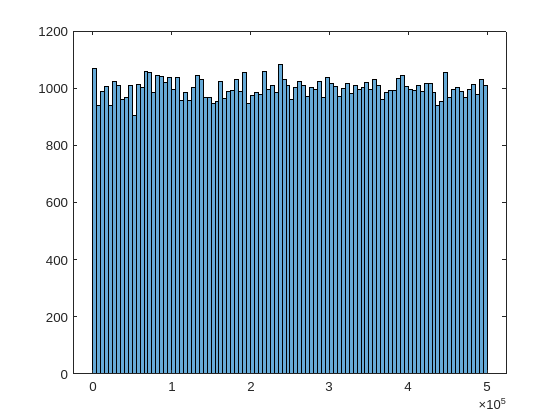

histogram(mod(hashes_1,length(hash_table_1)),100);

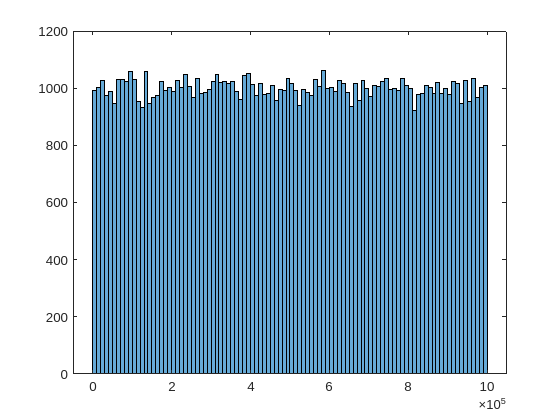

histogram(mod(hashes_1,length(hash_table_2)),100);

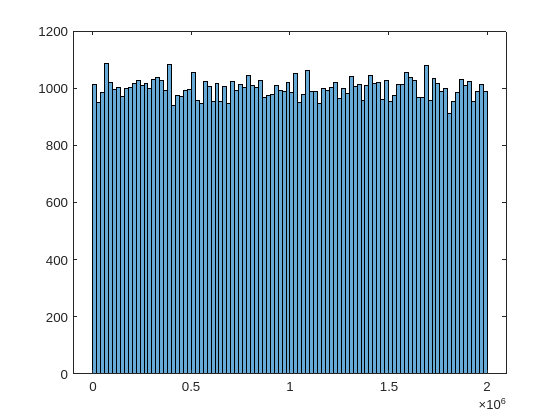

histogram(mod(hashes_1,length(hash_table_3)),100);

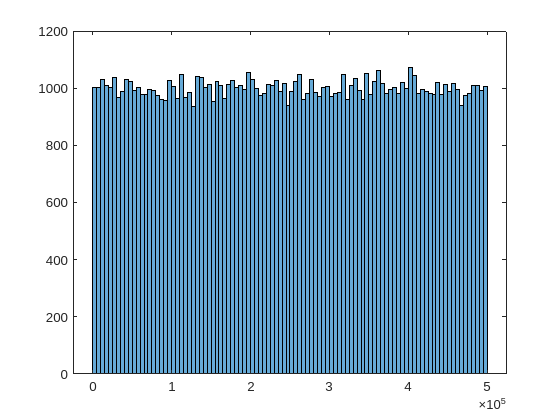

histogram(mod(hashes_2,length(hash_table_1)),100);

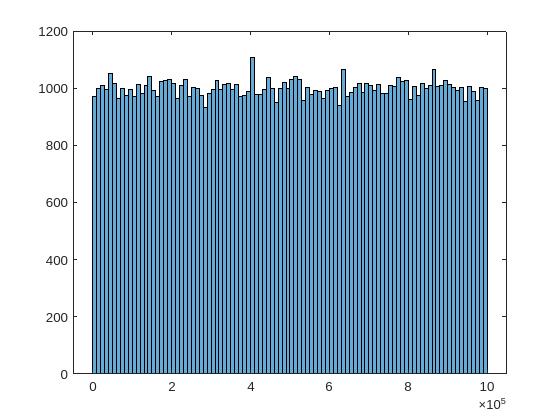

histogram(mod(hashes_2,length(hash_table_2)),100);

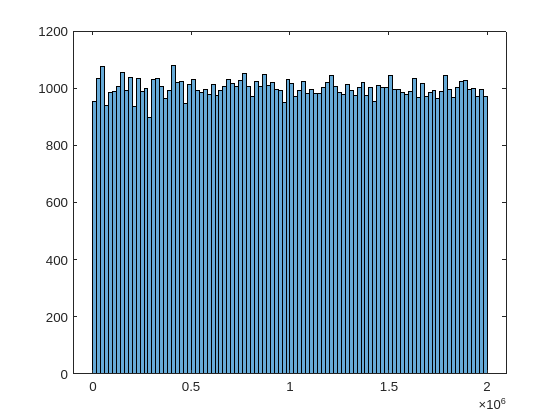

histogram(mod(hashes_2,length(hash_table_3)),100);

b)

# 3

1)

function hashes = createHash(value,k)
    hashes = zeros(1,k);
    str = value;
    for i = 1:k
        str = [str num2str(i)];
        h = string2hash(str);
        hashes(i) = h;
    end
end

function filter = FilterInit(n)
    filter = false(zeros(1,n));
end

function FilterInsert(value,bloom_filter,k)
    hashes = createHash(value,k);
    for i = 1:length(hashes)
        bloom_filter(mod(hashes(i),length(bloom_filter))) = true;
    end
end

function ismember = FilterContains(value,bloom_filter,k)
    hashes = createHash(value,k);
    for i = 1:length(hashes)
        if bloom_filter(hashes(i))
            ismember = true;
        else
            ismember = false;
        end
    end
end

U1 = generateKeys(1e3,6,20,['A':'Z','a':'z']);
filter = FilterInit(8000);
for i = 1:length(U1)
    FilterInsert(U1{i},filter,3);
end

ans = 3.5325e+09

Attempt to grow array along ambiguous dimension.

Error in Aula6>FilterInsert (line 98)
        bloom_filter(mod(hashes(i),length(bloom_filter))) = true;

filter